# Irminger 1 CTD Casts

First produces a rough map of the CTD casts from Irminger 1 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen. 

Kristen Fogaren 12/3/2020

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

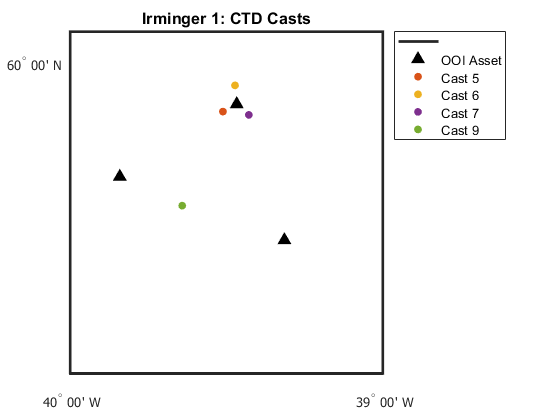

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year1')
load Irm1_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(KN22104005down.latitude),nanmean(KN22104005down.longitude),'.','markersize',20,'Color',red)
plotm(nanmean(KN22104006down.latitude),nanmean(KN22104006down.longitude),'.','markersize',20,'Color',yellow)
plotm(nanmean(KN22104007down.latitude),nanmean(KN22104007down.longitude),'.','markersize',20,'Color',purple)
plotm(nanmean(KN22104009down.latitude),nanmean(KN22104009down.longitude),'.','markersize',20,'Color',green)

title('Irminger 1: CTD Casts')
legend('','OOI Asset','Cast 5','Cast 6','Cast 7','Cast 9','Location','bestoutside')

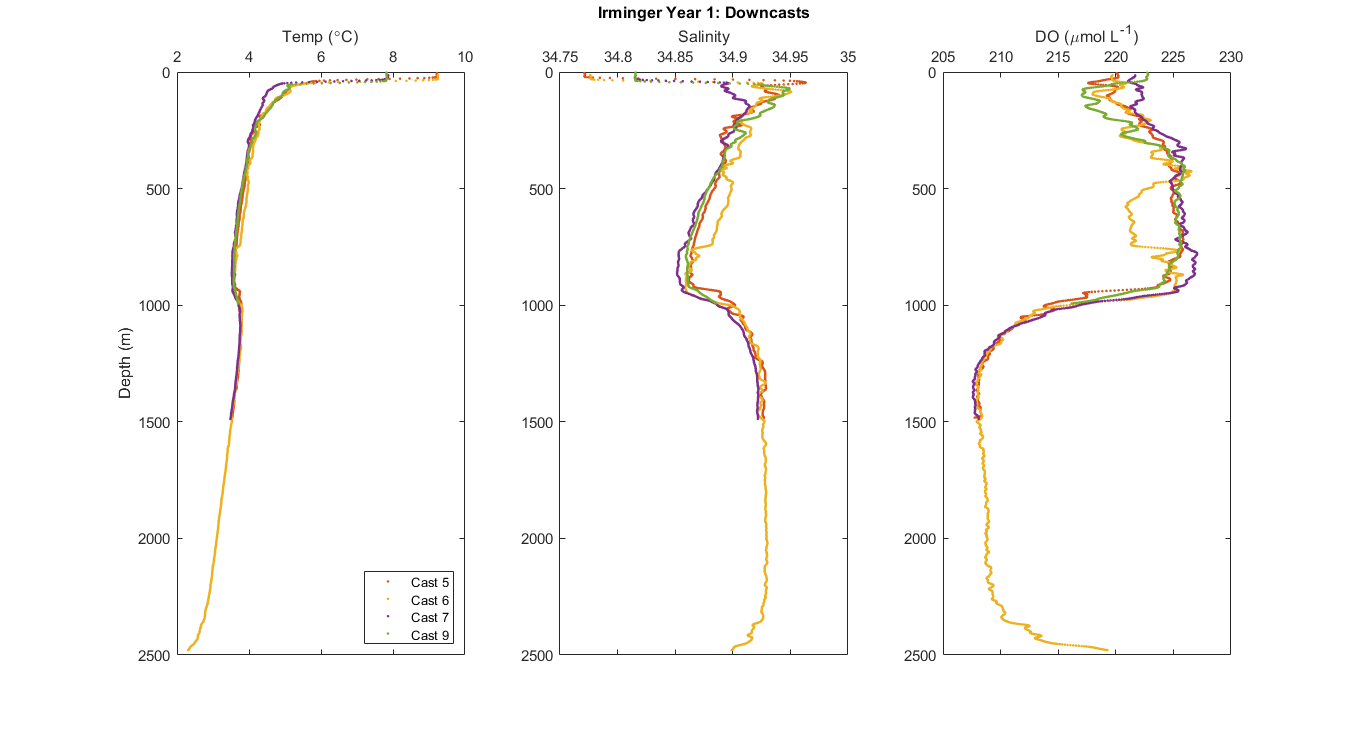

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(KN22104005down.t090C,KN22104005down.depSM,'.','Color',red);
hold on
plot(KN22104006down.t090C,KN22104006down.depSM,'.','Color',yellow);
plot(KN22104007down.t090C,KN22104007down.depSM,'.','Color',purple);
plot(KN22104009down.t090C,KN22104009down.depSM,'.','Color',green);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 5','Cast 6','Cast 7','Cast 9','Location','SE')

s2 = subplot(1,3,2);
plot(KN22104005down.sal00,KN22104005down.depSM,'.','Color',red);
hold on
plot(KN22104006down.sal00,KN22104006down.depSM,'.','Color',yellow);
plot(KN22104007down.sal00,KN22104007down.depSM,'.','Color',purple);
plot(KN22104009down.sal00,KN22104009down.depSM,'.','Color',green);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 1: Downcasts')

s3 = subplot(1,3,3);
plot(KN22104005down.sbeox0MLL*44.661,KN22104005down.depSM,'.','Color',red);
hold on
plot(KN22104006down.sbeox0MLL*44.661,KN22104006down.depSM,'.','Color',yellow);
plot(KN22104007down.sbeox0MLL*44.661,KN22104007down.depSM,'.','Color',purple);
plot(KN22104009down.sbeox0MLL*44.661,KN22104009down.depSM,'.','Color',green);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

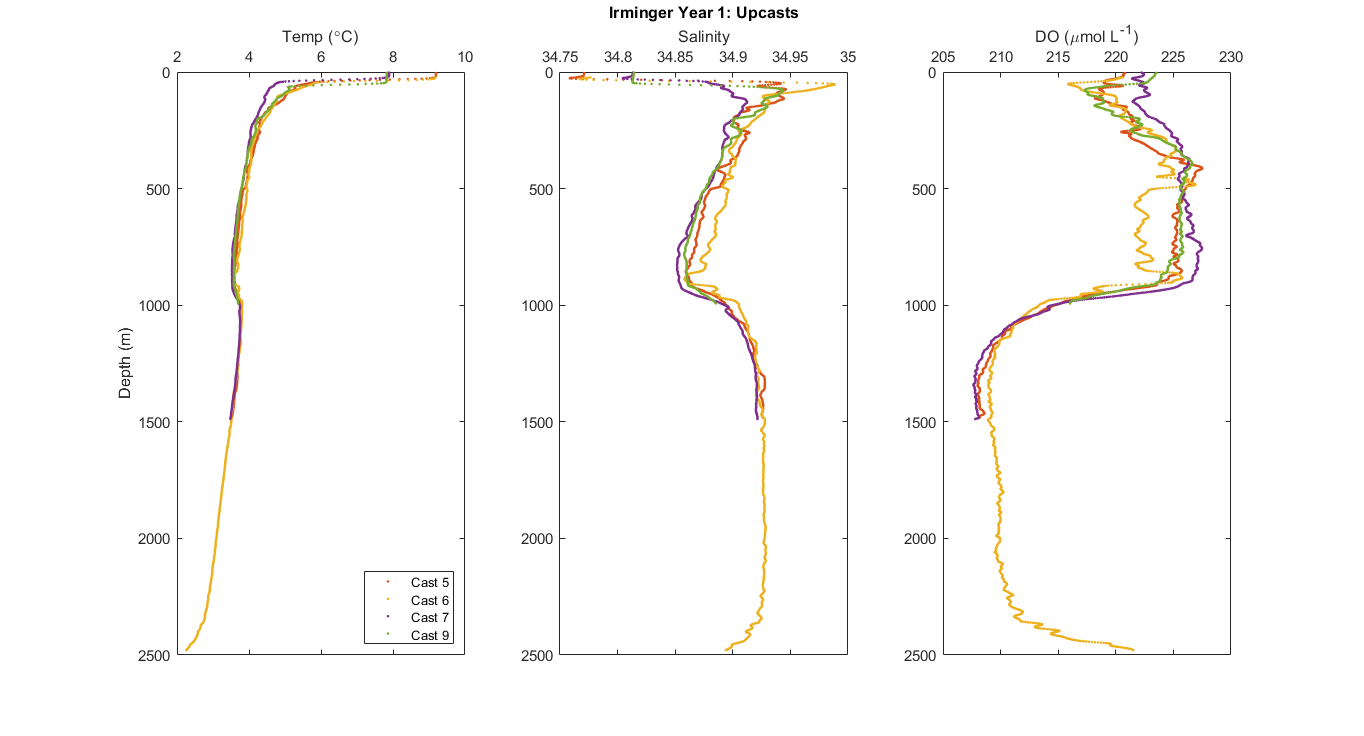

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(KN22104005up.t090C,KN22104005up.depSM,'.','Color',red);
hold on
plot(KN22104006up.t090C,KN22104006up.depSM,'.','Color',yellow);
plot(KN22104007up.t090C,KN22104007up.depSM,'.','Color',purple);
plot(KN22104009up.t090C,KN22104009up.depSM,'.','Color',green);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 5','Cast 6','Cast 7','Cast 9','Location','SE')

s2 = subplot(1,3,2);
plot(KN22104005up.sal00,KN22104005up.depSM,'.','Color',red);
hold on
plot(KN22104006up.sal00,KN22104006up.depSM,'.','Color',yellow);
plot(KN22104007up.sal00,KN22104007up.depSM,'.','Color',purple);
plot(KN22104009up.sal00,KN22104009up.depSM,'.','Color',green);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 1: Upcasts')

s3 = subplot(1,3,3);
plot(KN22104005up.sbeox0MLL*44.661,KN22104005up.depSM,'.','Color',red);
hold on
plot(KN22104006up.sbeox0MLL*44.661,KN22104006up.depSM,'.','Color',yellow);
plot(KN22104007up.sbeox0MLL*44.661,KN22104007up.depSM,'.','Color',purple);
plot(KN22104009up.sbeox0MLL*44.661,KN22104009up.depSM,'.','Color',green);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

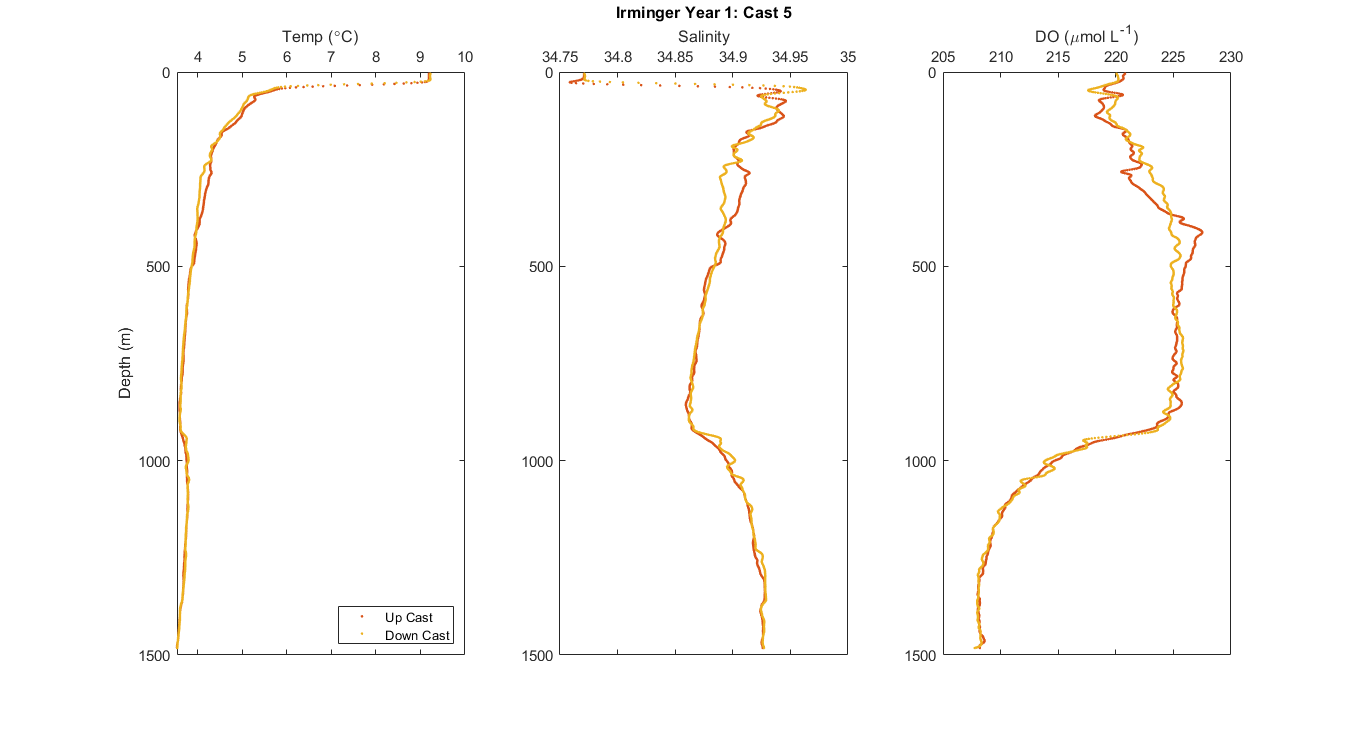

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(KN22104005up.t090C,KN22104005up.depSM,'.','Color',red);
hold on
plot(KN22104005down.t090C,KN22104005down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(KN22104005up.sal00,KN22104005up.depSM,'.','Color',red);
hold on
plot(KN22104005down.sal00,KN22104005down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 1: Cast 5')

s3 = subplot(1,3,3);
plot(KN22104005up.sbeox0MLL*44.661,KN22104005up.depSM,'.','Color',red);
hold on
plot(KN22104005down.sbeox0MLL*44.661,KN22104005down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

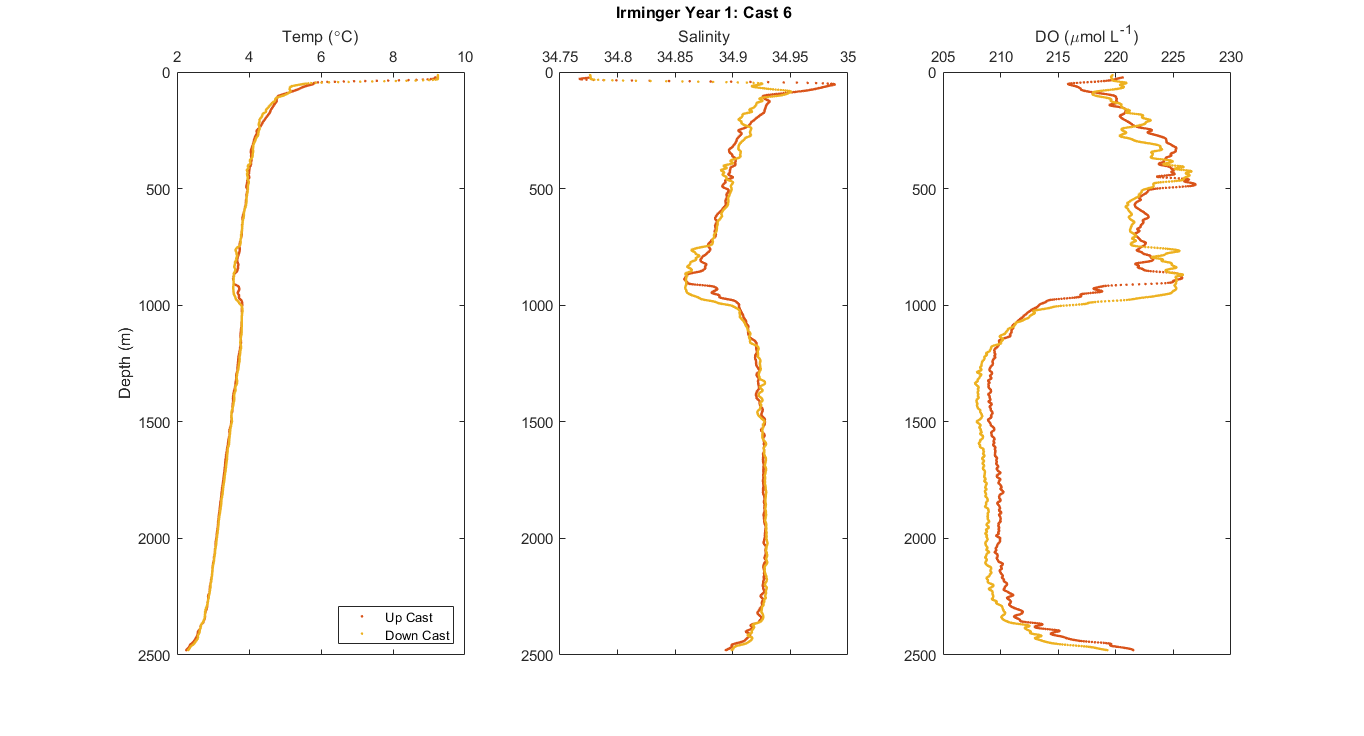


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(KN22104006up.t090C,KN22104006up.depSM,'.','Color',red);
hold on
plot(KN22104006down.t090C,KN22104006down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(KN22104006up.sal00,KN22104006up.depSM,'.','Color',red);
hold on
plot(KN22104006down.sal00,KN22104006down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 1: Cast 6')

s3 = subplot(1,3,3);
plot(KN22104006up.sbeox0MLL*44.661,KN22104006up.depSM,'.','Color',red);
hold on
plot(KN22104006down.sbeox0MLL*44.661,KN22104006down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

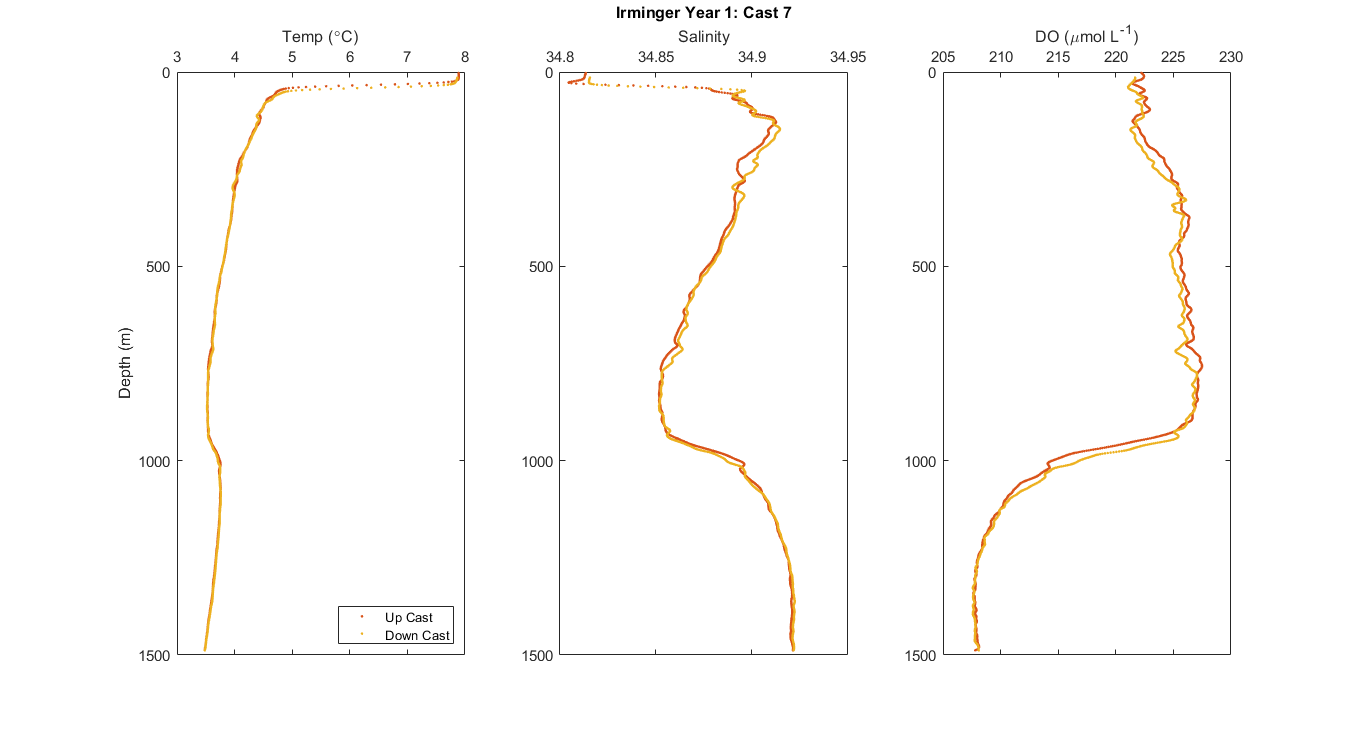


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(KN22104007up.t090C,KN22104007up.depSM,'.','Color',red);
hold on
plot(KN22104007down.t090C,KN22104007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(KN22104007up.sal00,KN22104007up.depSM,'.','Color',red);
hold on
plot(KN22104007down.sal00,KN22104007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 1: Cast 7')

s3 = subplot(1,3,3);
plot(KN22104007up.sbeox0MLL*44.661,KN22104007up.depSM,'.','Color',red);
hold on
plot(KN22104007down.sbeox0MLL*44.661,KN22104007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

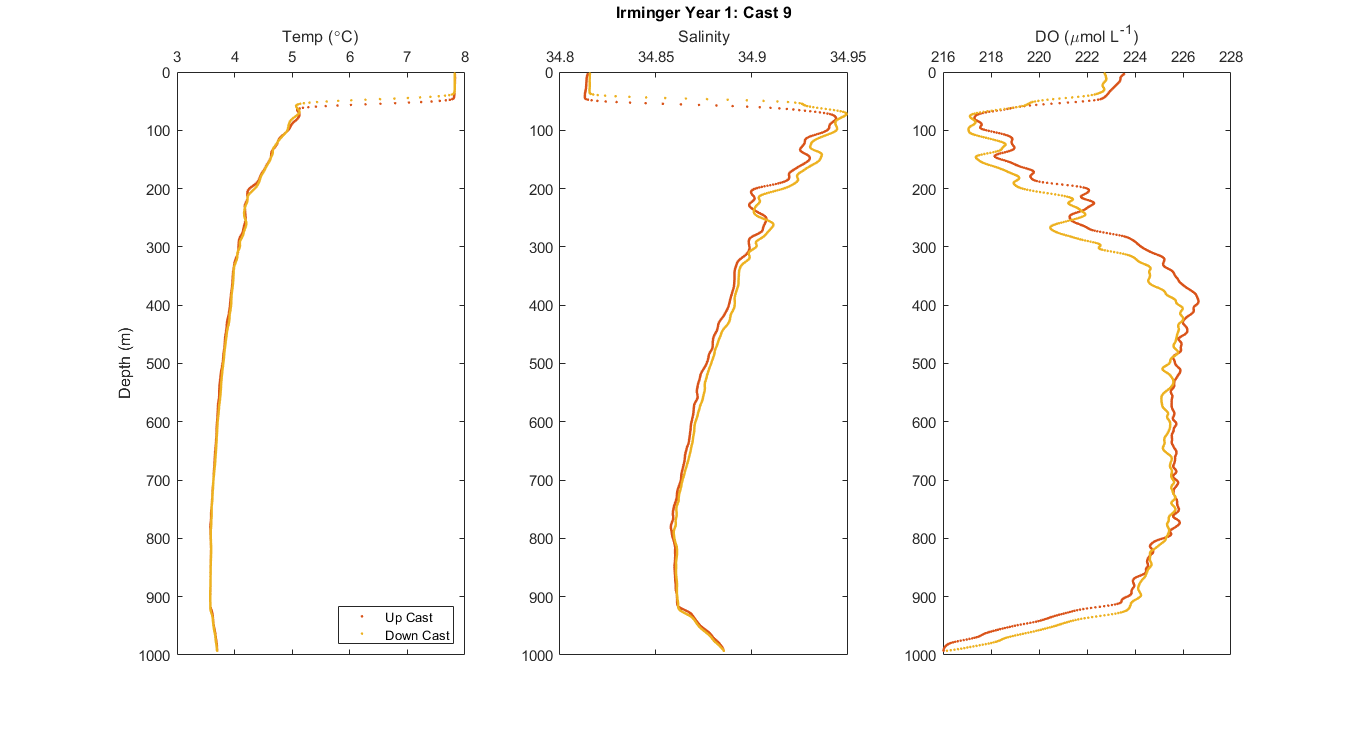


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(KN22104009up.t090C,KN22104009up.depSM,'.','Color',red);
hold on
plot(KN22104009down.t090C,KN22104009down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(KN22104009up.sal00,KN22104009up.depSM,'.','Color',red);
hold on
plot(KN22104009down.sal00,KN22104009down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 1: Cast 9')

s3 = subplot(1,3,3);
plot(KN22104009up.sbeox0MLL*44.661,KN22104009up.depSM,'.','Color',red);
hold on
plot(KN22104009down.sbeox0MLL*44.661,KN22104009down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')